## Calculo ~vo/~d simbólico

Vs = sym('V_s')     % Tension de entrada

$$Vs = V_{s}$$

rsw = sym('r_sw')   % Resistencia del switch (mos) encendido

$$rsw = r_{\mathrm{sw}}$$

rlp = sym('r_Lp')   % Resistencia serie del primario

$$rlp = r_{\mathrm{Lp}}$$

Ld = sym('L_d')     % Inductancia de dispersión

$$Ld = L_{d}$$

Lm = sym('L_m')     % Inductancia de magnetización

$$Lm = L_{m}$$

n = sym('n')        % Relación de transformación N1/N2

$$n = n$$

rls = sym('r_Ls')   % Resistencia serie del secundario

$$rls = r_{\mathrm{Ls}}$$

C = sym('C')        % Capacitancia

$$C = C$$

rc = sym('r_C')     % Resistencia serie del capacitor

$$rc = r_{C}$$

R = sym('R')        % Carga

$$R = R$$

D = sym('D')        % Duty cycle

$$D = \text{D}$$


s = sym('s')        % Frecuencia

$$s = s$$


rlseq = rls * n * n

$$rlseq = n^{2}\,r_{\mathrm{Ls}}$$

Ceq   = C / (n * n)

$$Ceq = \frac{C}{n^{2}}$$

rceq  = rc * n * n

$$rceq = n^{2}\,r_{C}$$

Req   = R * n * n

$$Req = R\,n^{2}$$


Aon = [-(rlp+rsw)/(Ld+Lm), 0; 0, -1/(Ceq*(Req+rceq))]

$$Aon = \left(\begin{array}{cc} -\frac{r_{\mathrm{Lp}}+r_{\mathrm{sw}}}{L_{d}+L_{m}} & 0\\ 0 & -\frac{n^{2}}{C\,\left(R\,n^{2}+n^{2}\,r_{C}\right)} \end{array}\right)$$

Bon = [1/(Ld+Lm); 0]

$$Bon = \left(\begin{array}{c} \frac{1}{L_{d}+L_{m}}\\ 0 \end{array}\right)$$

Con = [0, Req/(Req + rceq)]

$$Con = \left(\begin{array}{cc} 0 & \frac{R\,n^{2}}{R\,n^{2}+n^{2}\,r_{C}} \end{array}\right)$$


Aoff = [-(Req*rceq + Req*rlseq + rceq*rlseq)/(Lm*(Req+rceq)), -Req/(Lm*(Req+rceq)); Req/(Ceq*(Req+rceq)), -1/(Ceq*(Req+rceq))]

$$Aoff = \begin{array}{l} \left(\begin{array}{cc} -\frac{n^{4}\,r_{C}\,r_{\mathrm{Ls}}+R\,n^{4}\,r_{C}+R\,n^{4}\,r_{\mathrm{Ls}}}{L_{m}\,\sigma_{1}} & -\frac{R\,n^{2}}{L_{m}\,\sigma_{1}}\\ \frac{R\,n^{4}}{C\,\sigma_{1}} & -\frac{n^{2}}{C\,\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=R\,n^{2}+n^{2}\,r_{C} \end{array}$$

Boff = [0; 0]

Boff =      0
     0


Coff = [(Req*rceq)/(Req+rceq), Req/(Req+rceq)]

$$Coff = \left(\begin{array}{cc} \frac{R\,n^{4}\,r_{C}}{R\,n^{2}+n^{2}\,r_{C}} & \frac{R\,n^{2}}{R\,n^{2}+n^{2}\,r_{C}} \end{array}\right)$$


A_p = Aon*D + Aoff*(1-D)

$$A\_p = \begin{array}{l} \left(\begin{array}{cc} \frac{\left(\text{D}-1\right)\,\left(n^{4}\,r_{C}\,r_{\mathrm{Ls}}+R\,n^{4}\,r_{C}+R\,n^{4}\,r_{\mathrm{Ls}}\right)}{L_{m}\,\sigma_{1}}-\frac{\text{D}\,\left(r_{\mathrm{Lp}}+r_{\mathrm{sw}}\right)}{L_{d}+L_{m}} & \frac{R\,n^{2}\,\left(\text{D}-1\right)}{L_{m}\,\sigma_{1}}\\ -\frac{R\,n^{4}\,\left(\text{D}-1\right)}{C\,\sigma_{1}} & \frac{n^{2}\,\left(\text{D}-1\right)}{C\,\sigma_{1}}-\frac{\text{D}\,n^{2}}{C\,\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=R\,n^{2}+n^{2}\,r_{C} \end{array}$$

B_p = Bon*D + Boff*(1-D)

$$B\_p = \left(\begin{array}{c} \frac{\text{D}}{L_{d}+L_{m}}\\ 0 \end{array}\right)$$

C_p = Con*D + Coff*(1-D)

$$C\_p = \left(\begin{array}{cc} -\frac{R\,n^{4}\,r_{C}\,\left(\text{D}-1\right)}{R\,n^{2}+n^{2}\,r_{C}} & \frac{\text{D}\,R\,n^{2}}{R\,n^{2}+n^{2}\,r_{C}}-\frac{R\,n^{2}\,\left(\text{D}-1\right)}{R\,n^{2}+n^{2}\,r_{C}} \end{array}\right)$$


Xs_Vs = (s*eye(2)-A_p)\B_p

%Vo_Vs = simplify(C_p*Xs_Vs)
Xest = subs(Xs_Vs*Vs,s,0)

$$Xest = \begin{array}{l} \left(\begin{array}{c} \frac{\text{D}\,L_{m}\,V_{s}\,\left(R+r_{C}\right)}{\sigma_{1}}\\ -\frac{\text{D}\,L_{m}\,R\,V_{s}\,n^{2}\,\left(R+r_{C}\right)\,\left(\text{D}-1\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{d}\,R^{2}\,n^{2}+L_{m}\,R^{2}\,n^{2}+L_{d}\,R\,n^{2}\,r_{C}+L_{m}\,R\,n^{2}\,r_{C}+L_{d}\,R\,n^{2}\,r_{\mathrm{Ls}}+L_{m}\,R\,n^{2}\,r_{\mathrm{Ls}}+L_{d}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}+L_{m}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}-2\,\text{D}\,L_{d}\,R^{2}\,n^{2}-2\,\text{D}\,L_{m}\,R^{2}\,n^{2}+\text{D}\,L_{m}\,R\,r_{\mathrm{Lp}}+\text{D}\,L_{m}\,R\,r_{\mathrm{sw}}+{\text{D}}^{2}\,L_{d}\,R^{2}\,n^{2}+{\text{D}}^{2}\,L_{m}\,R^{2}\,n^{2}+\text{D}\,L_{m}\,r_{C}\,r_{\mathrm{Lp}}+\text{D}\,L_{m}\,r_{C}\,r_{\mathrm{sw}}-\text{D}\,L_{d}\,R\,n^{2}\,r_{C}-\text{D}\,L_{m}\,R\,n^{2}\,r_{C}-\text{D}\,L_{d}\,R\,n^{2}\,r_{\mathrm{Ls}}-\text{D}\,L_{m}\,R\,n^{2}\,r_{\mathrm{Ls}}-\text{D}\,L_{d}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}}-\text{D}\,L_{m}\,n^{2}\,r_{C}\,r_{\mathrm{Ls}} \end{array}$$


dD = sym('dD')

$$dD = \mathrm{dD}$$


dX_dD = (s*eye(2)-A_p)\((Aon-Aoff)*Xest+(Bon-Boff)*Vs)

dVo_dD = simplify(C_p*dX_dD + (Con-Coff)*Xest)


[num,den] = numden(dVo_dD)

$$num = -L_{m}\,R\,V_{s}\,n^{2}\,{\left(R+r_{C}\right)}^{2}\,\left(C\,r_{C}\,s+1\right)\,\left({\text{D}}^{2}\,L_{m}\,r_{\mathrm{Lp}}+{\text{D}}^{2}\,L_{m}\,r_{\mathrm{sw}}+\text{D}\,{L_{m}}^{2}\,s-L_{d}\,R\,n^{2}-L_{m}\,R\,n^{2}-L_{d}\,n^{2}\,r_{\mathrm{Ls}}-L_{m}\,n^{2}\,r_{\mathrm{Ls}}+2\,\text{D}\,L_{d}\,R\,n^{2}+2\,\text{D}\,L_{m}\,R\,n^{2}+2\,\text{D}\,L_{d}\,n^{2}\,r_{\mathrm{Ls}}+2\,\text{D}\,L_{m}\,n^{2}\,r_{\mathrm{Ls}}-{\text{D}}^{2}\,L_{d}\,R\,n^{2}-{\text{D}}^{2}\,L_{m}\,R\,n^{2}-{\text{D}}^{2}\,L_{d}\,n^{2}\,r_{\mathrm{Ls}}-{\text{D}}^{2}\,L_{m}\,n^{2}\,r_{\mathrm{Ls}}+\text{D}\,L_{d}\,L_{m}\,s\right)$$

[num_coeffs,n_] = coeffs(num,s)

$$num\_coeffs = \begin{array}{l} \left(\begin{array}{ccc} -C\,L_{m}\,R\,V_{s}\,n^{2}\,r_{C}\,{\left(R+r_{C}\right)}^{2}\,\sigma_{2} & C\,L_{m}\,R\,V_{s}\,n^{2}\,r_{C}\,{\left(R+r_{C}\right)}^{2}\,\sigma_{1}-L_{m}\,R\,V_{s}\,n^{2}\,{\left(R+r_{C}\right)}^{2}\,\sigma_{2} & L_{m}\,R\,V_{s}\,n^{2}\,{\left(R+r_{C}\right)}^{2}\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{d}\,R\,n^{2}-{\text{D}}^{2}\,L_{m}\,r_{\mathrm{sw}}-{\text{D}}^{2}\,L_{m}\,r_{\mathrm{Lp}}+L_{m}\,R\,n^{2}+L_{d}\,n^{2}\,r_{\mathrm{Ls}}+L_{m}\,n^{2}\,r_{\mathrm{Ls}}-2\,\text{D}\,L_{d}\,R\,n^{2}-2\,\text{D}\,L_{m}\,R\,n^{2}-2\,\text{D}\,L_{d}\,n^{2}\,r_{\mathrm{Ls}}-2\,\text{D}\,L_{m}\,n^{2}\,r_{\mathrm{Ls}}+{\text{D}}^{2}\,L_{d}\,R\,n^{2}+{\text{D}}^{2}\,L_{m}\,R\,n^{2}+{\text{D}}^{2}\,L_{d}\,n^{2}\,r_{\mathrm{Ls}}+{\text{D}}^{2}\,L_{m}\,n^{2}\,r_{\mathrm{Ls}}\\ \sigma_{2}=\text{D}\,{L_{m}}^{2}+\text{D}\,L_{d}\,L_{m} \end{array}$$

$$n\_ = \left(\begin{array}{ccc} s^{2} & s & 1 \end{array}\right)$$

[den_coeffs,d_] = coeffs(den,s)

$$d\_ = \left(\begin{array}{ccc} s^{2} & s & 1 \end{array}\right)$$

## Reemplazo de símbolos por valores numéricos

Vs_ = 300       % Tension de entrada

Vs_ = 300

rsw_ = 0        % Resistencia del switch (mos) encendido

rsw_ = 0

rlp_ = 1e-3        % Resistencia serie del primario

rlp_ = 1.0000e-03

Lm_ = 0.00264375     % Inductancia de magnetización

Lm_ = 0.0026

Ld_ = 0.00029375 % Inductancia de dispersión

Ld_ = 2.9375e-04

n_ = 25/4       % Relación de transformación N1/N3

n_ = 6.2500

rls_ = 1e-3        % Resistencia serie del secundario

rls_ = 1.0000e-03

C_ = 4.7e-6   % Capacitancia

C_ = 4.7000e-06

rc_ = 0.5         % Resistencia serie del capacitor

rc_ = 0.5000

R_ = 100         % Carga

R_ = 100

D_ = 0.25        % Duty cycle

D_ = 0.2500


my_sims = [Vs, rsw, rlp, Lm, Ld, n, rls, C, rc, R, D]

$$my\_sims = \left(\begin{array}{ccccccccccc} V_{s} & r_{\mathrm{sw}} & r_{\mathrm{Lp}} & L_{m} & L_{d} & n & r_{\mathrm{Ls}} & C & r_{C} & R & \text{D} \end{array}\right)$$

my_vals = [Vs_,rsw_,rlp_,Lm_,Ld_,n_,rls_,C_,rc_,R_,D_]

my_vals =   300.0000         0    0.0010    0.0026    0.0003    6.2500    0.0010    0.0000    0.5000  100.0000    0.2500



num_coeffs_ = double(subs(num_coeffs,my_sims,my_vals))

num_coeffs_ = 	1.0e+08 *

   -0.0000    0.0000    2.0198


den_coeffs_ = double(subs(den_coeffs,my_sims,my_vals))

den_coeffs_ = 	1.0e+05 *

    0.0000    0.0000    4.2219


sys = tf(num_coeffs_,den_coeffs_)/n_ % salida Vo real es V2/V1 = N2/N1 veces la del backboost

sys =
 
  -0.0001428 s^2 + 413.9 s + 2.02e08
  ----------------------------------
  0.001497 s^2 + 11.44 s + 2.639e06
 
Continuous-time transfer function.



## Grafico de curvas de ~vo/~d

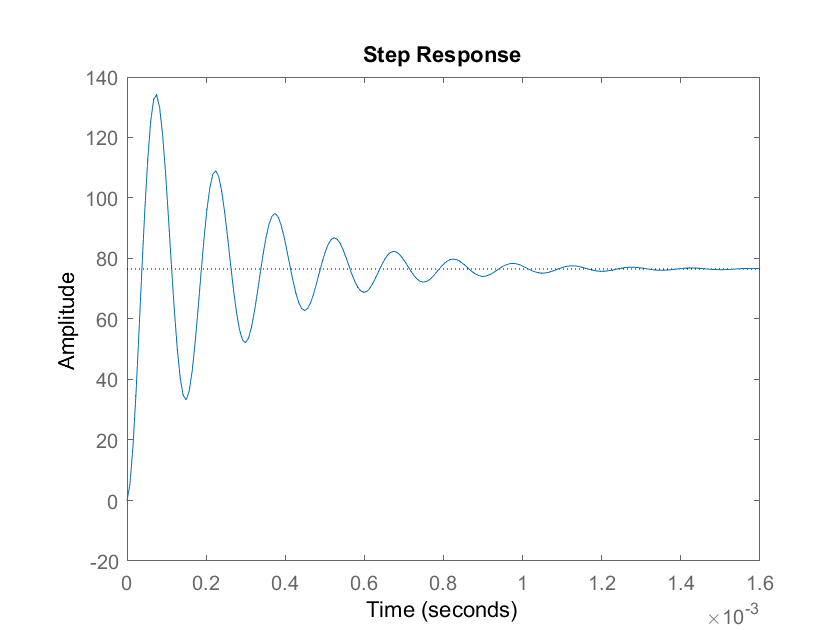

step(sys)

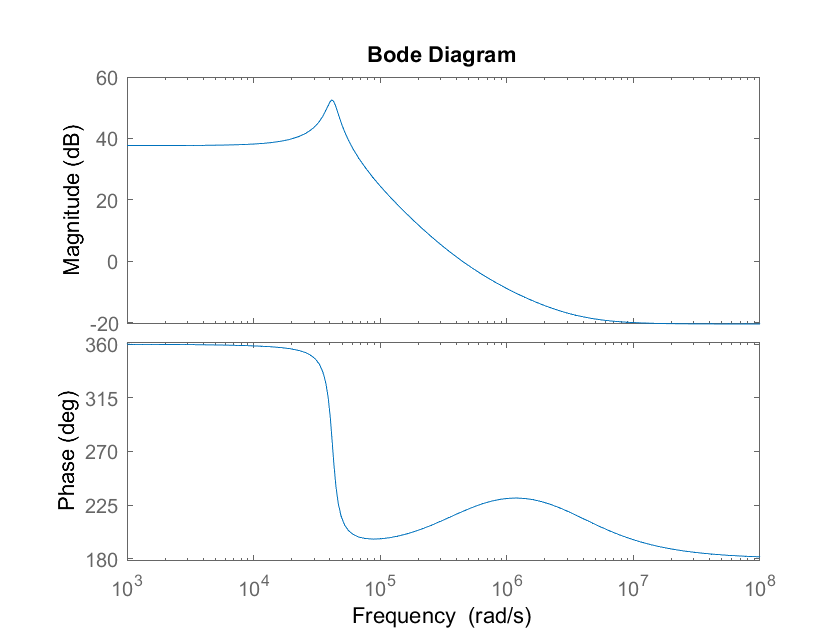

figure('Name', 'Bode');
bode(sys)

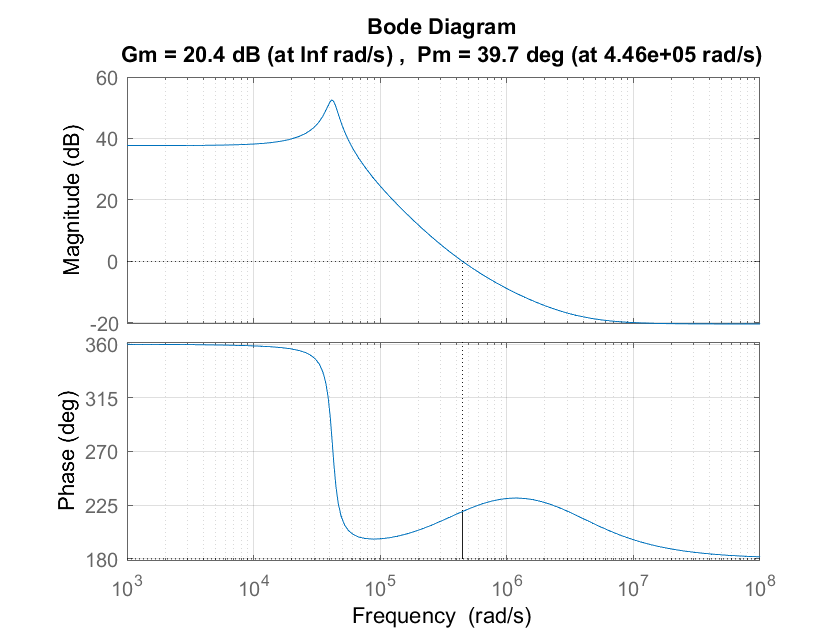

margin(sys)
grid on

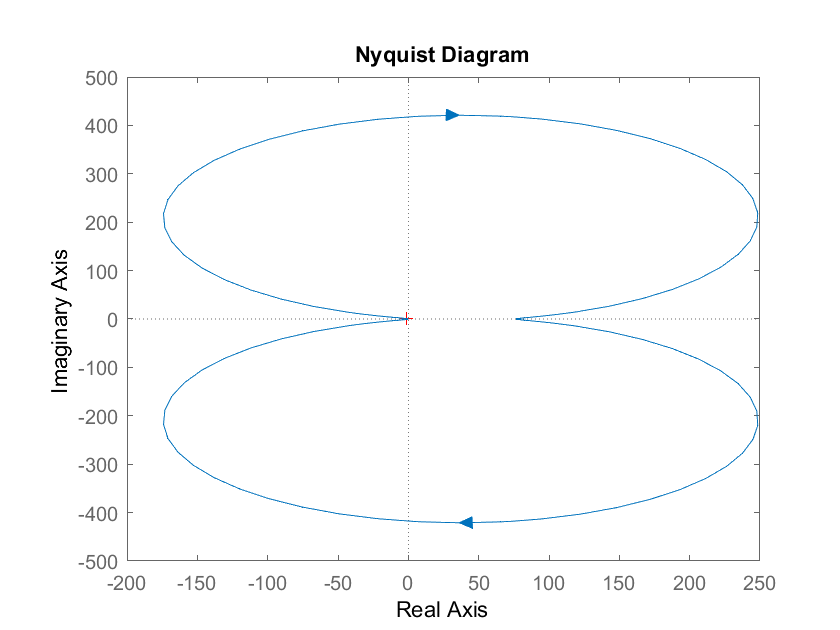


nyquist(sys)

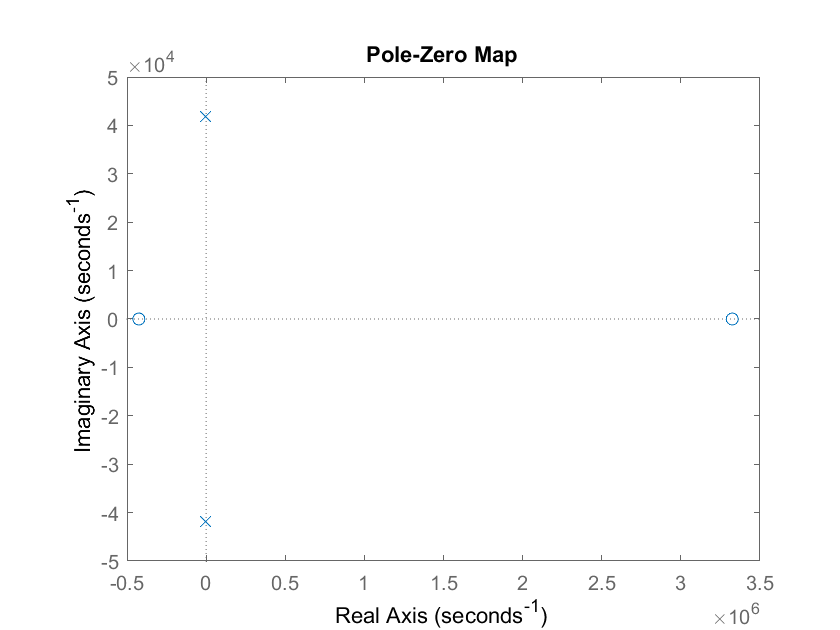

pzplot(sys)

## Vo_comp/Vout3

Rbo = 10e3

Rbo = 10000

Rao = 1.2e3

Rao = 1200

Vocomp_Vout3 = Rao/(Rao+Rbo)

Vocomp_Vout3 = 0.1071

## D/Vea

Vclk = 3 % a 3.5

Vclk = 3

D_Vea = 1/(2*Vclk)

D_Vea = 0.1667

## Vo_comp/Vea

Vocomp_Vea = D_Vea * sys * Vocomp_Vout3 % D/Vea * dVo/dD * Vocomp/Vo3

Vocomp_Vea =
 
  -2.549e-06 s^2 + 7.391 s + 3.607e06
  -----------------------------------
   0.001497 s^2 + 11.44 s + 2.639e06
 
Continuous-time transfer function.



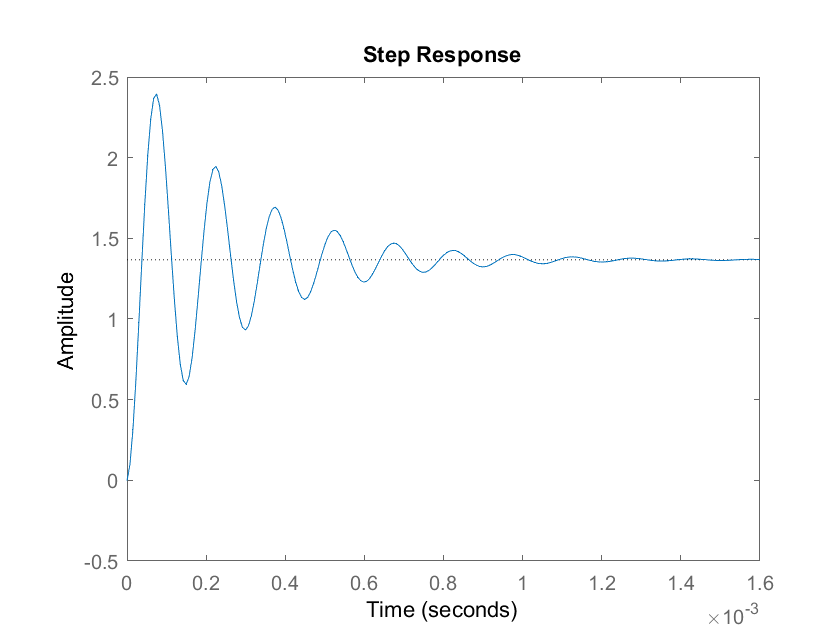


step(Vocomp_Vea)

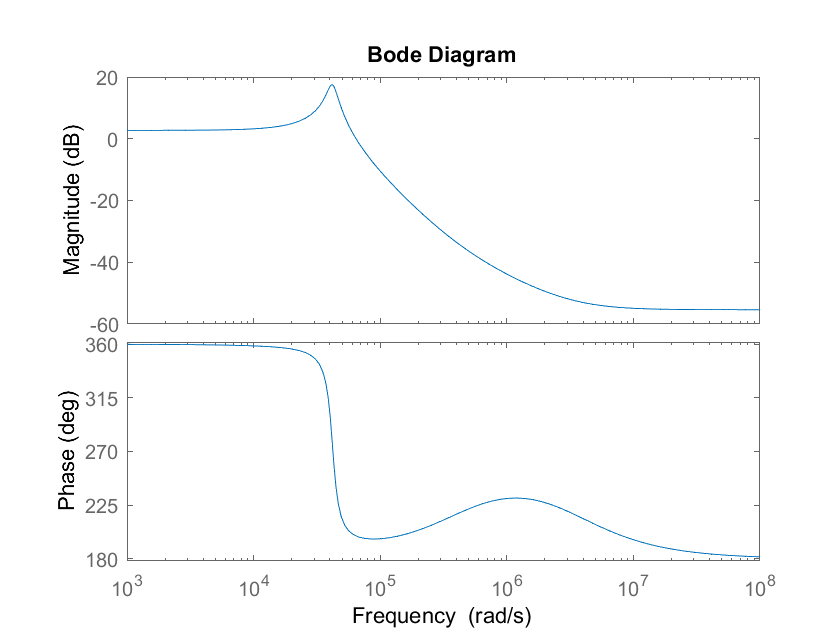

figure('Name', 'Bode');
bode(Vocomp_Vea)

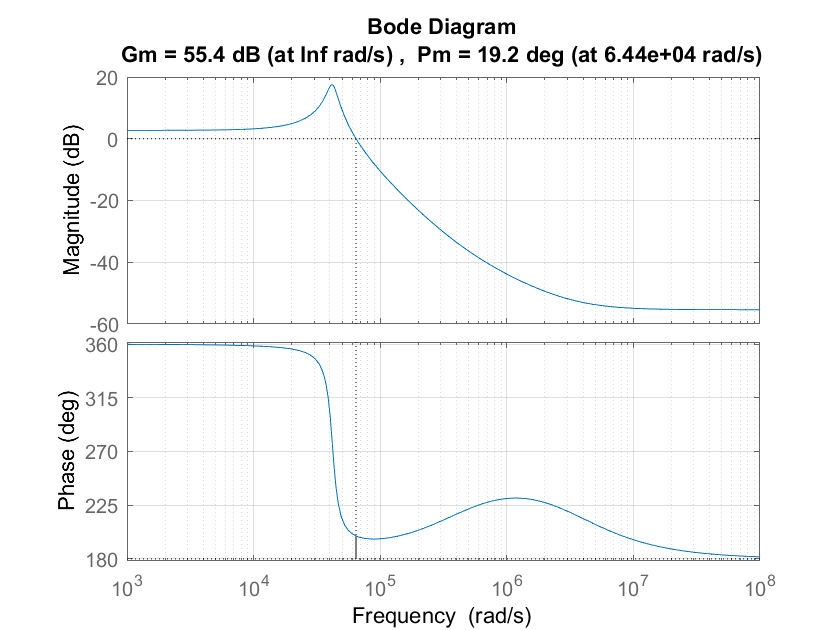

margin(Vocomp_Vea)
grid on

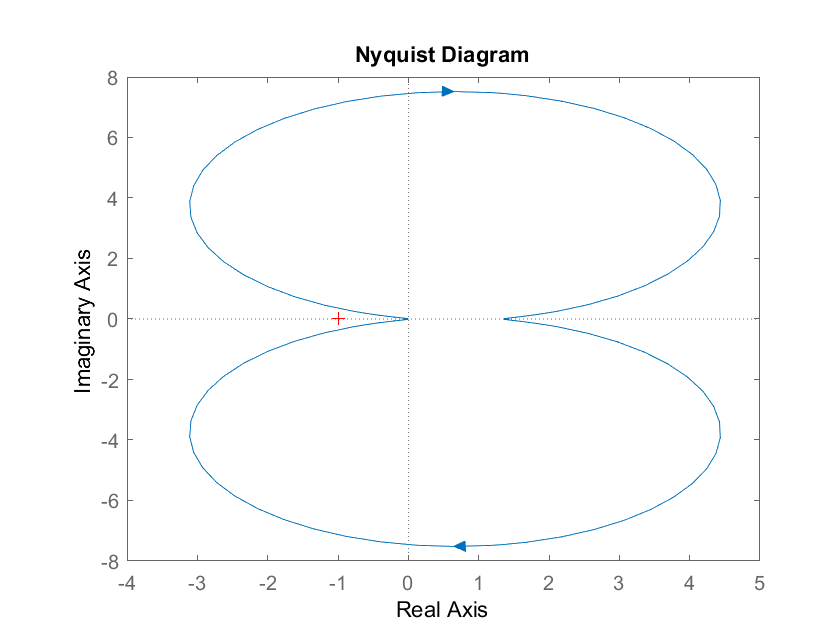


nyquist(Vocomp_Vea)

pzplot(Vocomp_Vea)

## Calculo de Vea/Vo_comp

Fs = 75e3

Fs = 75000

Fco = 0.2*Fs

Fco = 15000


Lossco = abs(evalfr(Vocomp_Vea,1j*2*pi*Fco))

Lossco = 0.3449

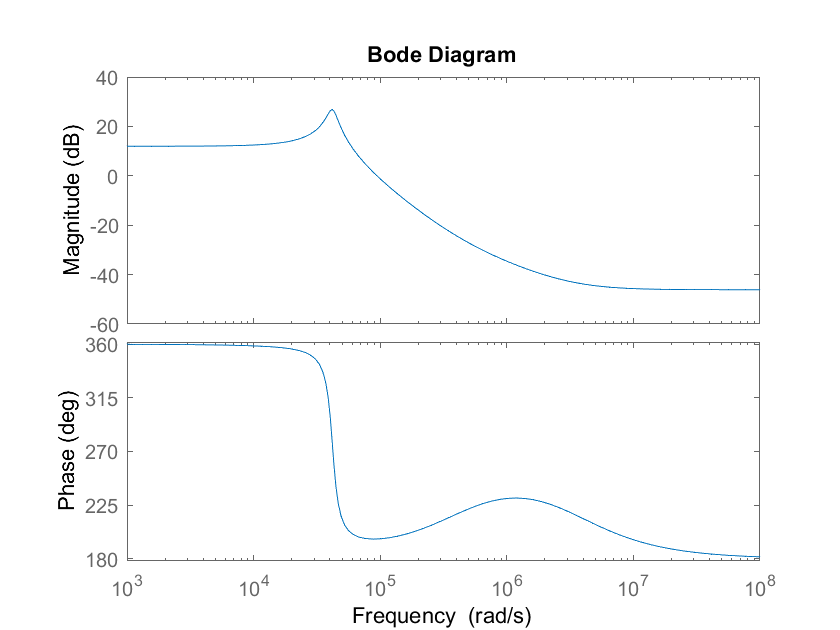

bode(Vocomp_Vea/Lossco)

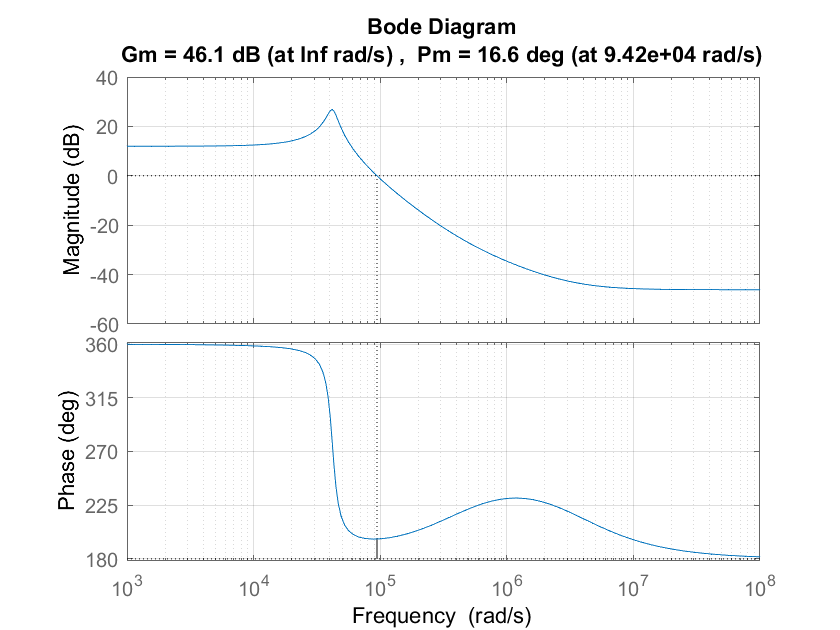

margin(Vocomp_Vea/Lossco)
grid on

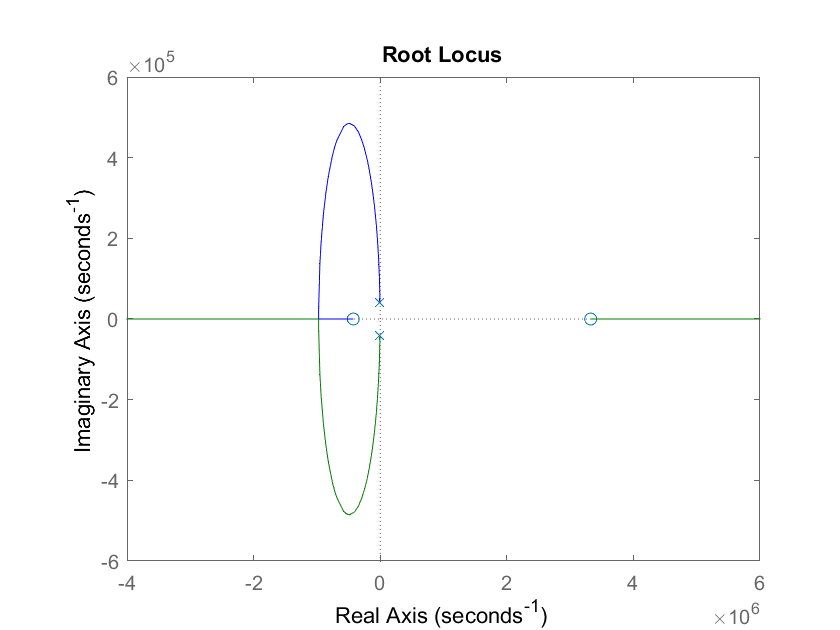

rlocus(Vocomp_Vea/Lossco)

%controlSystemDesigner(Vocomp_Vea/Lossco)

syms R1 R2 C1 C2

opamp = -(R2*C1*s+1)/(R1*(R2*C1*C2*s*s+(C1+C2)*s))

$$opamp = -\frac{C_{1}\,R_{2}\,s+1}{R_{1}\,\left(C_{1}\,C_{2}\,R_{2}\,s^{2}+\left(C_{1}+C_{2}\right)\,s\right)}$$

[opnum,opden] = numden(opamp)

$$opnum = -C_{1}\,R_{2}\,s-1$$

$$opden = R_{1}\,\left(C_{1}\,s+C_{2}\,s+C_{1}\,C_{2}\,R_{2}\,s^{2}\right)$$

%[opnumcoeff,n__] = coeffs(opnum,s)
%[opdencoeff,d__] = coeffs(opden,s)

%op_z = -opnumcoeff(2)/opnumcoeff(1)
%op_p = -opdencoeff(2)/opdencoeff(1)


R2_ = 100e3

R2_ = 100000

Gea = 1/Lossco

Gea = 2.8992

R1_ = R2_/Gea

R1_ = 3.4492e+04


Fz = Fco/100

Fz = 150

Fp = Fco*100

Fp = 1500000


C1_ = 1/(2*pi*R2_*Fz)

C1_ = 1.0610e-08

C2_ = 1/(2*pi*R2_*Fp)

C2_ = 1.0610e-12


Vea_Vocomp = subs(opamp,[R1,R2,C1,C2],[R1_,R2_,C1_,C2_])

$$Vea\_Vocomp = -\frac{137438953472\,\left(\frac{5010586458934615625\,s}{4722366482869645213696}+1\right)}{4740598588493045\,\left(\frac{1645345286550908625042837818446875\,s^{2}}{1461501637330902918203684832716283019655932542976}+\frac{3284066315521562435\,s}{309485009821345068724781056}\right)}$$

[VVnum,VVden] = numden(Vea_Vocomp)

$$VVnum = -213126777488534329839650601824380685331285719331635200000\,s-200867255532373784442745261542645325315275374222849104412672$$

$$VVden = 7799921543006922084802591144676501950208639484375\,s^{2}+73519879907127349284985778290856855204559246568141619200\,s$$

[VVnumcoef,n___] = (coeffs(VVnum,s))

$$VVnumcoef = \left(\begin{array}{cc} -213126777488534329839650601824380685331285719331635200000 & -200867255532373784442745261542645325315275374222849104412672 \end{array}\right)$$

$$n\_\_\_ = \left(\begin{array}{cc} s & 1 \end{array}\right)$$

[VVdencoef,d___] = (coeffs(VVden,s))

$$VVdencoef = \left(\begin{array}{cc} 7799921543006922084802591144676501950208639484375 & 73519879907127349284985778290856855204559246568141619200 \end{array}\right)$$

$$d\_\_\_ = \left(\begin{array}{cc} s^{2} & s \end{array}\right)$$

VVnumcoef = double(VVnumcoef)

VVnumcoef = 	1.0e+59 *

   -0.0021   -2.0087


VVdencoef = double([VVdencoef(1),VVdencoef(2),0])

VVdencoef = 	1.0e+55 *

    0.0000    7.3520         0


Vea_Vocomp_ = tf(VVnumcoef,VVdencoef)

Vea_Vocomp_ =
 
  -2.131e56 s - 2.009e59
  -----------------------
  7.8e48 s^2 + 7.352e55 s
 
Continuous-time transfer function.



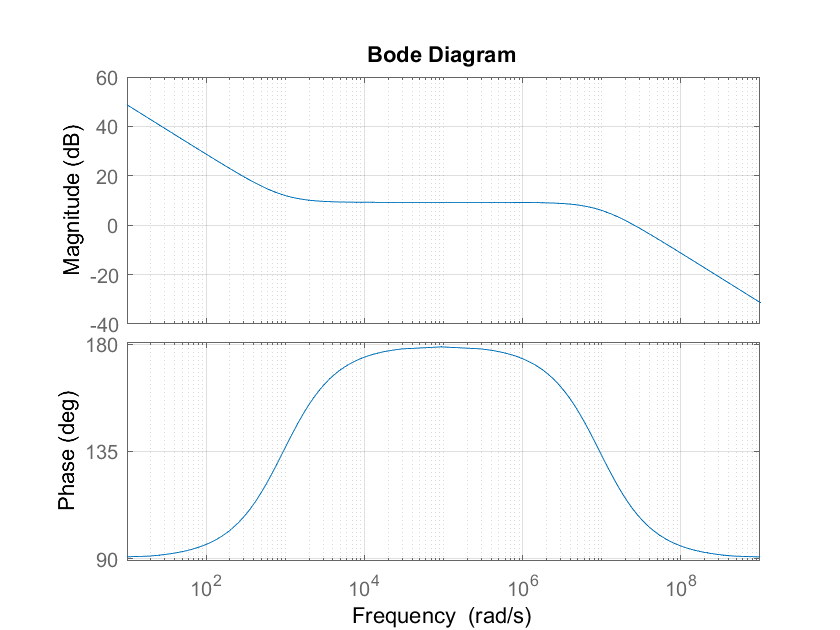


bode(Vea_Vocomp_)
%margin(Vea_Vocomp_)
grid on

Aol = - Vea_Vocomp_ * Vocomp_Vea

Aol =
 
                                      
  -3.478e52 s^3 + 1.008e59 s^2        
                                      
               + 4.929e64 s + 4.637e67
                                      
  ------------------------------------
                                      
  7.474e47 s^4 + 7.05e54 s^3          
                                      
           + 5.515e58 s^2 + 1.242e64 s
                                      
 
Continuous-time transfer function.



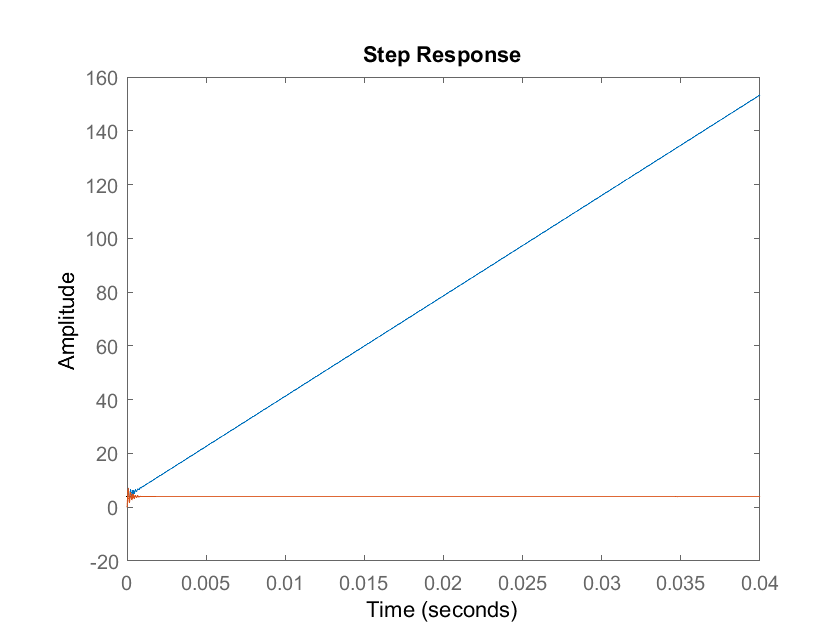

step(Aol,Vocomp_Vea/Lossco)

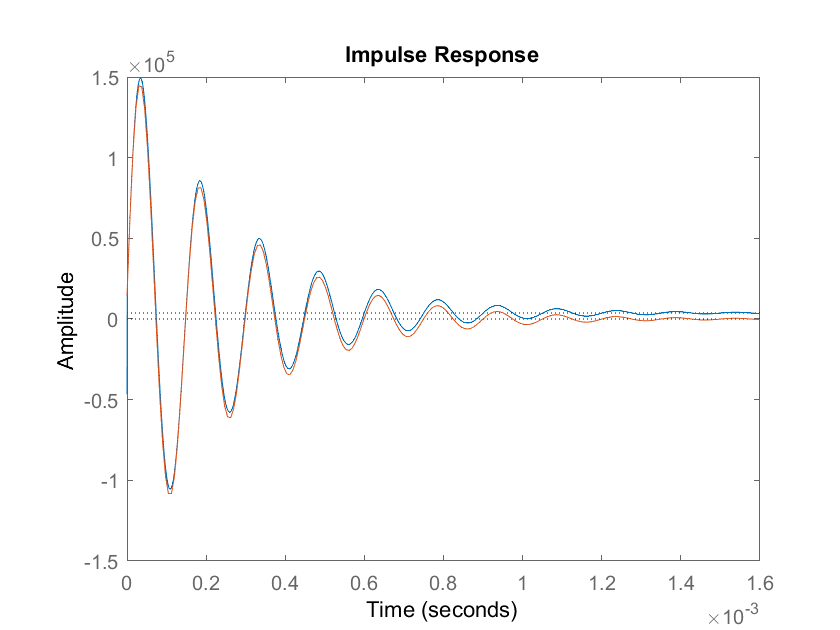

impulse(Aol,Vocomp_Vea/Lossco)

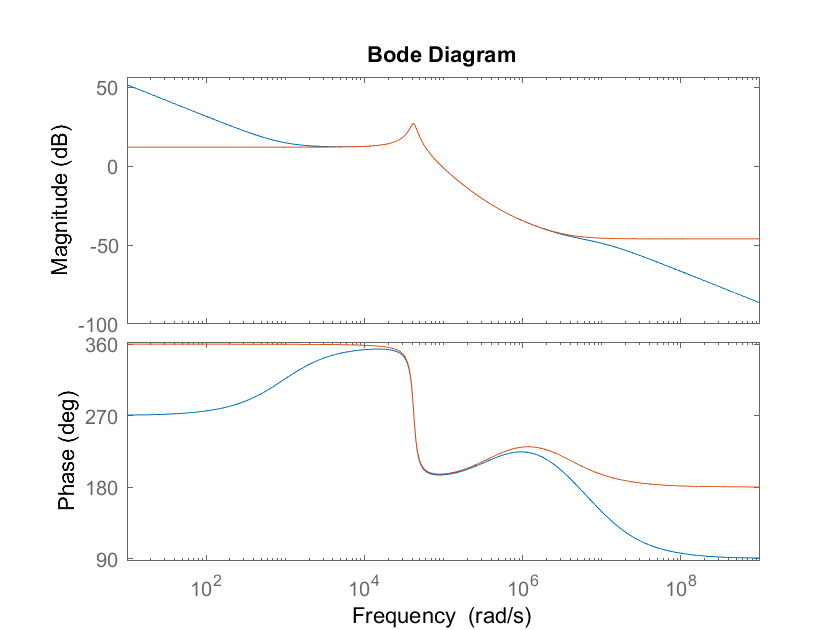

bode(Aol,Vocomp_Vea/Lossco)

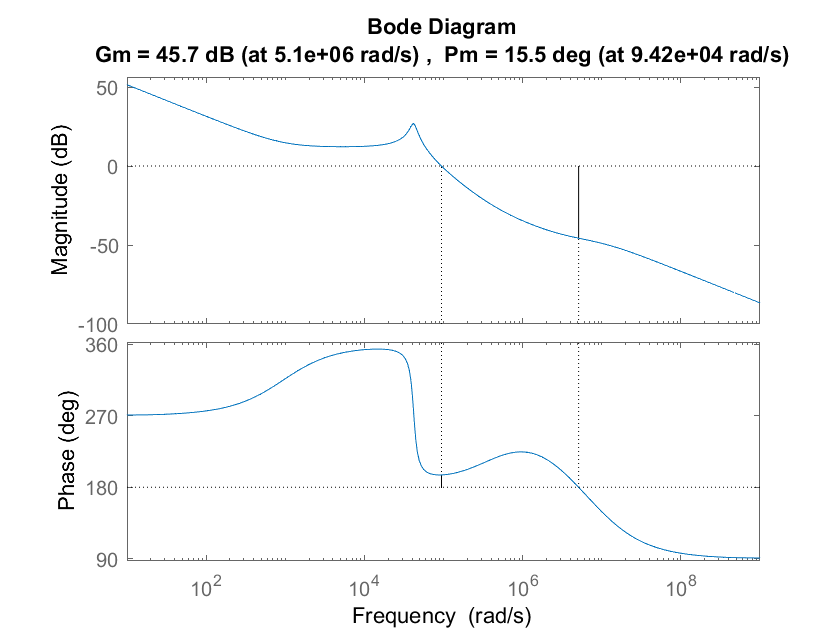

margin(Aol)

margin(Vocomp_Vea/Lossco)
grid on

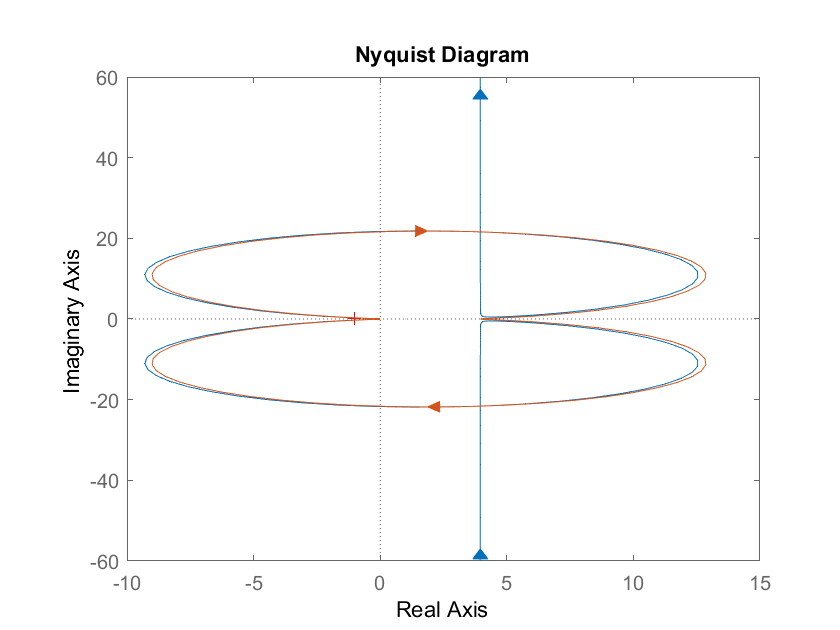


nyquist(Aol,Vocomp_Vea/Lossco)

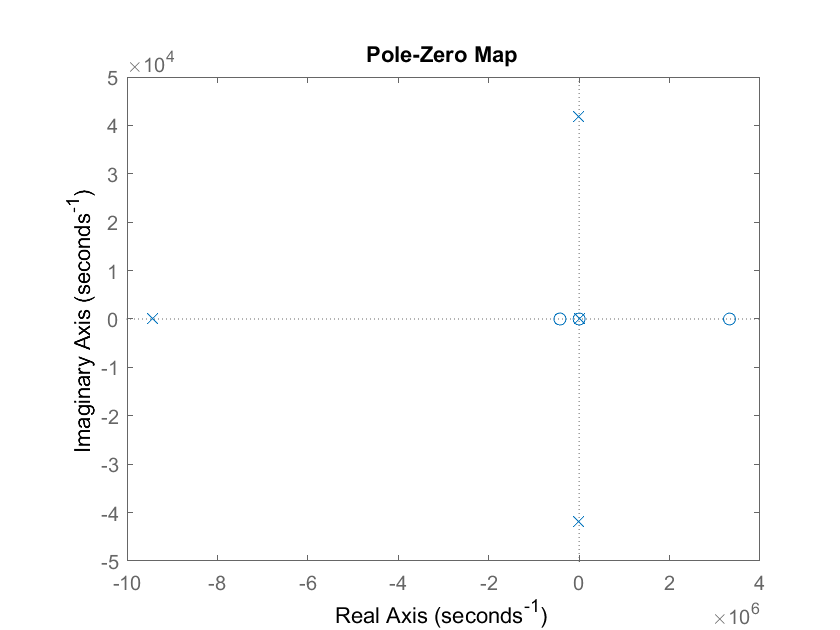

pzplot(Aol)